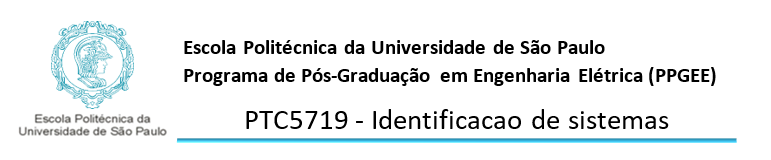

# Elton Inacio Alves Junior - 12501745

# LISTA 1

1 - Considere um processo linear, invariante no tempo, de tempo contínuo, descrito pela  seguinte função de transferência:

**A**. Discretize o modelo do processo, supondo intervalo de amostragem T=1 s e a presença de  segurador de ordem zero (zero order hold). Doravante se designará por processo o modelo  em tempo contínuo, pois representa um processo real em tempo contínuo e por modelo do  processo a versão em tempo discreto, que representa um modelo do processo real. Implante em Simulink os modelos em tempo contínuo e em tempo discreto, aplicando um  método de integração numérica de passo fixo com $\Delta$t=0,01 s e uma decimação de 100 para  os dados analógicos. Para a parte digital empregue T=1 s. Suponha que ambos os modelos  sejam submetidos a uma entrada em degrau de 0,1 em t=0 s. Simule-os por 20 s. O sinal  de entrada u(t) para o modelo em tempo contínuo passa por um segurador de ordem zero.  Comente as diferenças na saída dos dois modelos. Para gerar os gráficos use o comando  plot para sinais em tempo contínuo e stairs para sinais em tempo discreto. Insira as duas  respostas em um mesmo gráfico, a fim de poder compará-las.

Utilizando o auxilio do MATLAB com a discertizando sistema usando função "c2d" do Matlab com T=1:

k  = 2;
tau = 10;
t_heta = 4;

% Sistema Contínuo
    Sisc = tf(k,[tau 1],'inputdelay',t_heta);

% Convertendo para discreto
    Sisd=c2d(Sisc,1,'zoh');
    
    

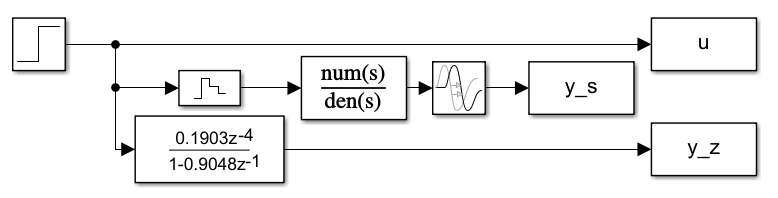

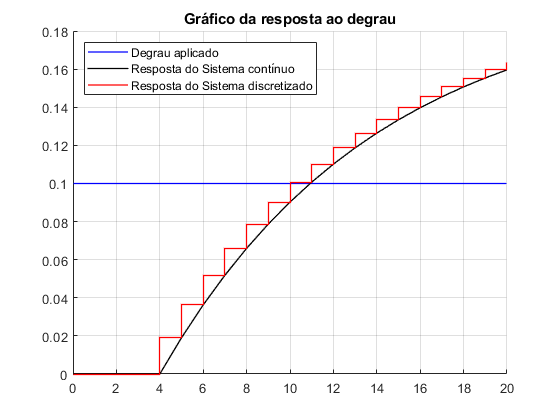

    Tsim = 20;
    sim('Lista_1_Simu_1');

    grid;
    hold on;
    stairs(t,u,'blue','linewidth',1);       % Degrau
    plot(t,y_s,'black','linewidth',1);     % Contínuo
    stairs(t,y_z,'red','linewidth',1);    % Discreto
    
    title({'Gráfico da resposta ao degrau'});
    legend('Degrau aplicado','Resposta do Sistema contínuo','Resposta do Sistema discretizado','location','northwest');    

**Comentários:** O modelo discretizado, se aproxima do modelo contínuo, provando que é fiel em representar o processo. Porém quanto menor fosse o valor de "T" (intervalo de amostragem), o modelo discreto se aproximaria ainda mais da curva do processo.

**B**. Suponha que o sinal medido de saída seja afetado por ruído aleatório com distribuição  gaussiana, com média nula e variância 1e-6. Mostre o gráfico de y(t) em tempo contínuo  afetado por ruído com entrada em degrau de 0,1 em t=0 s. Simule o processo por 20 s.

    clc;clear;close all;
warning off;

% Variáveis...
    grf_b=0;
    lne=1;
    variante=1e-6;
    k=2;
    tau=10;
    t_heta=4;

% Rodando simulação do Simulink
    Tsim = 20;
    

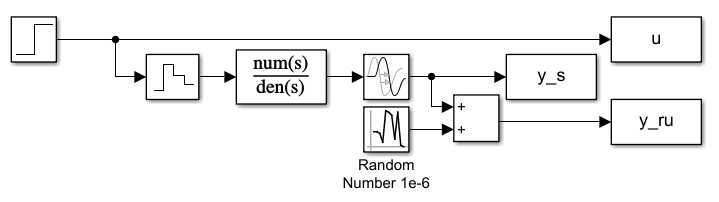

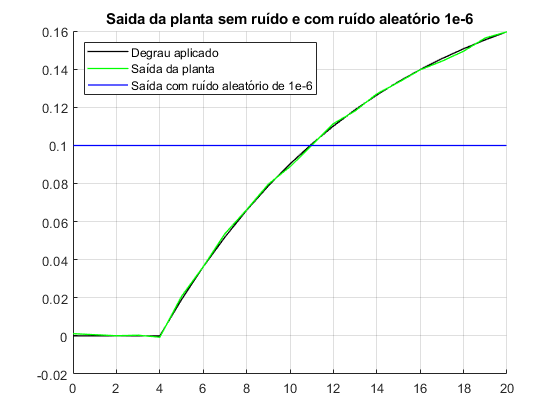

    sim('Lista_1_Simu_2');

% Plotando o gráfico
    grf_b = grf_b + 1;
    figure(grf_b);
    grid;
    hold on;
    plot(t,y_s,'black','linewidth',lne);     % Contínuo
    plot(t,y_ru,'green','linewidth',lne);
    stairs (t, u, 'blue','linewidth' ,lne); %degrau
    
    title({'Saida da planta sem ruído e com ruído aleatório 1e-6'});
    legend('Saída da planta','Saída com ruído aleatório de 1e-6','Degrau aplicado','location','northwest');

**Comentários:** Podemos observar na resposta gerada acima, ao se aplicar um ruído com a variância de , a resposta permanece bastante fiel a saída da planta sem o ruído.

**C**. Considere que o processo em tempo contínuo seja afetado por perturbações v(t), com v(t)  sendo gerado de três modos diferentes: v(t)=e(t), sendo que e(t) corresponde a ruído  branco com média nula e variância $\lambda^2$ , a qual pode assumir dois valores: 0,001 (baixa) e 0,1  (alta); e(t) passando por uma função de transferência de1ª ordem e e(t) passando por uma  função de transferência de 2ª ordem, conforme indicado a seguir:

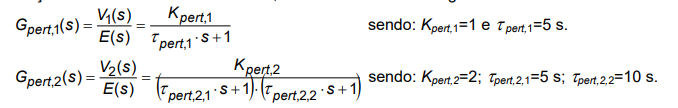

Utilize o seguinte código para distinguir as perturbações: 

**Vdireta_baixa** : perturbação v(t)=e(t) com variância $\lambda^2$  =0,001 (baixa) 

**Vdireta_alta **: perturbação v(t)=e(t) com variância $\lambda^2$  =0,1 (alta) 

**v1_ baixa** : perturbação com v(t)=e(t) filtrado por f.t. de 1ª ordem com variância $\lambda^2$  =0,001 

**v1_ alta** : perturbação com v(t)=e(t) filtrado por f.t. de 1ª ordem com variância $\lambda^2$ =0,1 

**v2 _ baixa **: perturbação com v(t)=e(t) filtrado por f.t. de 2ª ordem com variância $\lambda^2$  =0,001 

**v2_alta **: perturbação com v(t)=e(t) filtrado por f.t. de 2ª ordem com variância $\lambda^2$  =0,1 

Implante em Simulink os modelos de perturbação em tempo contínuo. Assuma que eles sejam submetidos a um sinal aleatório com intervalo de amostragem T com distribuição gaussiana, com média nula e variância 0,001 (baixa) e 0,1 (alta). Simule-os por 20 s. Comente  as diferenças na saída das três formas de perturbação, isto é, o efeito dos filtros lineares no  sinal aleatório. Gere a função de transferência discreta equivalente a cada uma das duas perturbações  citadas neste item, considerando T=1 s.

clc;clear;close all;

% Variáveis...
    grf_bax=0;
    grf_alt=0;
    
    lne=1;
    %variâncias
    bax=0.001;
    alt=0.1;
    
    K_pert_1=1;
    Tau_pert_1=5;
    t_heta=4;
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;
    
    

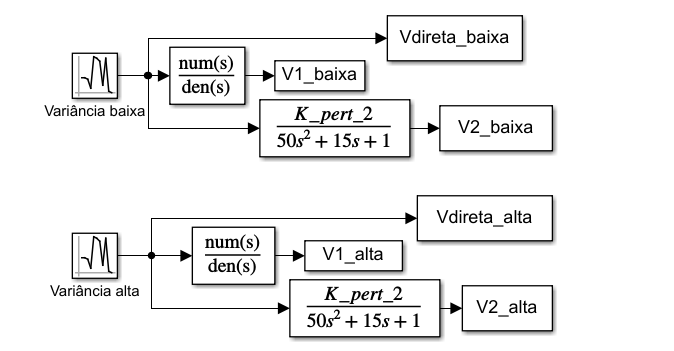

    
% Rodando simulação do Simulink
    Tsim = 20;
    sim('Lista_1_Simu_3');
    
% Sistema Contínuo
    Sisc1=tf(K_pert_1,[Tau_pert_1 1],'inputdelay',t_heta);
    Sisc2=tf(K_pert_2,[50 15 1],'inputdelay',t_heta);

% Convertendo para discreto
    Sisd1=c2d(Sisc1,1,'zoh');
    Sisd2=c2d(Sisc2,1,'zoh');

    
% Plotando o gráfico
ax1 = subplot(2,1,1);

    grf_bax = grf_bax + 1;
    figure(grf_bax);
    grid;
    hold on;
    plot(t,Vdireta_baixa,'black','linewidth',lne);       % Degrau
    plot(t,V1_baixa,'yellow','linewidth',lne);     % Contínuo
    plot(t,V2_baixa,'red','linewidth',lne);     % Contínuo
    
    title({'Saida com Ruído aleatório de baixa variância 0.001'});
    legend('V direta baixa','V1_ baixa','V2_ baixa','location','northwest');
    % Plotando o gráfico
ax2 = subplot(2,1,2);

    grf_alt = grf_alt + 1;
    figure(grf_alt);
    grid;
    hold on;
    plot(t,Vdireta_alta,'black','linewidth',lne);       % Degrau
    plot(t,V1_alta,'yellow','linewidth',lne);     % Contínuo
    plot(t,V2_alta,'red','linewidth',lne);     % Contínuo
    
    
    title({'Saida com Ruído aleatório de alta variância 0.1'});
    legend('V direta alta','V1_ alta','V2_ alta','location','northwest');

Utilizado função "c2d" no Matlab:

    Sisd1

Sisd1 =
 
             0.1813
  z^(-4) * ----------
           z - 0.8187
 
Sample time: 1 seconds
Discrete-time transfer function.



    Sisd2

Sisd2 =
 
            0.01811 z + 0.01639
  z^(-4) * ----------------------
           z^2 - 1.724 z + 0.7408
 
Sample time: 1 seconds
Discrete-time transfer function.



Como não é possivel verificar em detalhes a atuação dos filtros, abaixo é apresentado um  gráfico sem a perturbação não filtrada:

    clc;clear;close all;

% Variáveis...
    grf_bax=0;
    grf_alt=0;
    
    lne=1;
    %variâncias
    bax=0.001;
    alt=0.1;
    
    K_pert_1=1;
    Tau_pert_1=5;
    t_heta=4;
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;
    
  

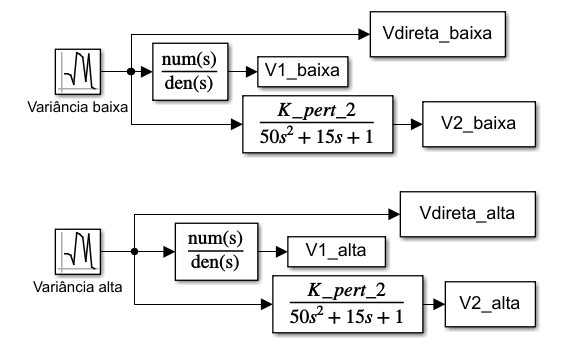

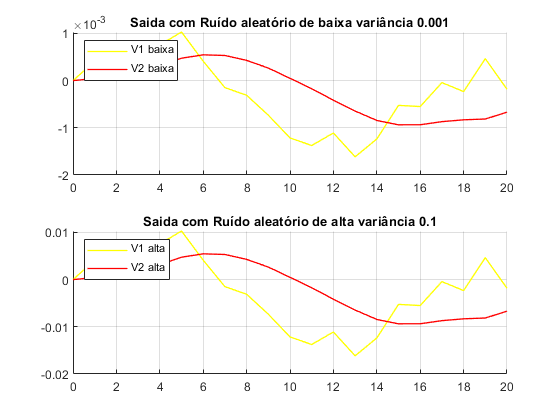

  
    
% Rodando simulação do Simulink
    Tsim = 20;
    sim('Lista_1_Simu_3');
    
% Sistema Contínuo
    Sisc1=tf(K_pert_1,[Tau_pert_1 1],'inputdelay',t_heta);
    Sisc2=tf(K_pert_2,[50 15 1],'inputdelay',t_heta);

% Convertendo para discreto
    Sisd1=c2d(Sisc1,1,'zoh');
    Sisd2=c2d(Sisc2,1,'zoh');

    
% Plotando o gráfico
ax1 = subplot(2,1,1);

    grf_bax = grf_bax + 1;
    figure(grf_bax);
    grid;
    hold on;
    %plot(t,Vdireta_baixa,'black','linewidth',lne);       % Degrau
    plot(t,V1_baixa,'yellow','linewidth',lne);     % Contínuo
    plot(t,V2_baixa,'red','linewidth',lne);     % Contínuo
    
    title({'Saida com Ruído aleatório de baixa variância 0.001'});
    legend('V1_ baixa','V2_ baixa','location','northwest');
  
    
% Plotando o gráfico
ax2 = subplot(2,1,2);

    grf_alt = grf_alt + 1;
    figure(grf_alt);
    grid;
    hold on;
    %plot(t,Vdireta_alta,'black','linewidth',lne);       % Degrau
    plot(t,V1_alta,'yellow','linewidth',lne);     % Contínuo
    plot(t,V2_alta,'red','linewidth',lne);     % Contínuo
    
    
    title({'Saida com Ruído aleatório de alta variância 0.1'});
    legend('V1_ alta','V2_ alta','location','northwest');

**Comentários: **Importante observarmos que embora os dois gráficos pareçam iguais, suas escalas do eixo y são diferentes, devido a amplitude da variância do sinal. Portanto, podemos perceber que a eficiência dos filtros de primeira ordem, são as mesmas, o que muda é a amplitude, devido a amplitude do sinal de entrada. O mesmo acontece com o filtro de segunda ordem.

**D.** Considere que se acrescentem perturbações aditivas ao processo. Implemente em Simulink  o modelo do processo acrescido do modelo das perturbações (somente na forma  analógica). Faça isto para as três formas de perturbação citadas na alínea “c” e para as  duas intensidades da perturbação. Plote os gráficos da saída y(t) afetada pelas  perturbações v(t), supondo que o processo seja submetido a uma entrada em degrau de  0,1 em t=0 s. Simule os modelos por 60 s. Comente o efeito das perturbações na saída do  processo, conforme se modifica a forma de gerar a perturbação e quando se lida com  perturbações com baixa e alta intensidade. Qual perturbação afeta mais a saída y(t)? 

    clc;clear;close all;

% Variáveis...
    grf_bax=0;
    grf_alt=0;
    
    lne=1;
    %variâncias
    bax=0.001;
    alt=0.1;
    
    k=2;
    tau=10;
    K_pert_1=1;
    Tau_pert_1=5;
    t_heta=4;
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;
    

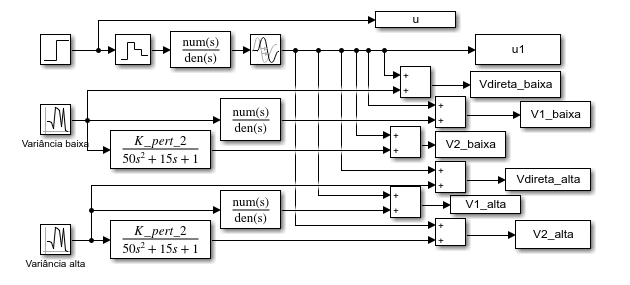

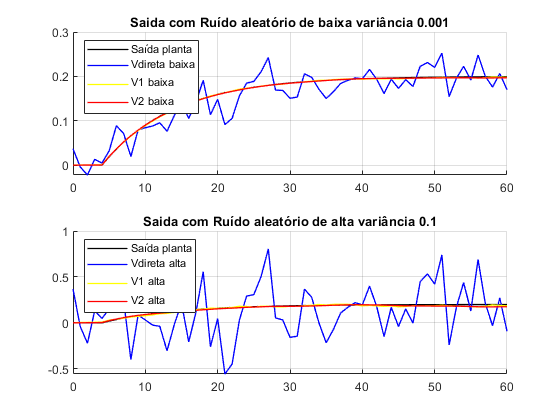

  
    
% Rodando simulação do Simulink
    Tsim = 60;
    sim('Lista_1_Simu_4');
% Sistema Contínuo
    Sisc1=tf(K_pert_1,[Tau_pert_1 1],'inputdelay',t_heta);
    Sisc2=tf(K_pert_2,[50 15 1],'inputdelay',t_heta);

% Convertendo para discreto
    Sisd1=c2d(Sisc1,1,'zoh');
    Sisd2=c2d(Sisc2,1,'zoh');

    
% Plotando o gráfico
ax1 = subplot(2,1,1);

    grf_bax = grf_bax + 1;
    figure(grf_bax);
    grid;
    hold on;
    plot(t,u1,'black','linewidth',lne);       % Degrau
    plot(t,Vdireta_baixa,'blue','linewidth',lne);       % Degrau
    plot(t,V1_baixa,'yellow','linewidth',lne);     % Contínuo
    plot(t,V2_baixa,'red','linewidth',lne);     % Contínuo
    
    title({'Saida com Ruído aleatório de baixa variância 0.001'});
    legend('Saída planta','Vdireta_ baixa','V1_ baixa','V2_ baixa','location','northwest');
  
    
% Plotando o gráfico
ax2 = subplot(2,1,2);

    grf_alt = grf_alt + 1;
    figure(grf_alt);
    grid;
    hold on;
    plot(t,u1,'black','linewidth',lne);       % Degrau
    plot(t,Vdireta_alta,'blue','linewidth',lne);       % Degrau
    plot(t,V1_alta,'yellow','linewidth',lne);     % Contínuo
    plot(t,V2_alta,'red','linewidth',lne);     % Contínuo
    
    
    title({'Saida com Ruído aleatório de alta variância 0.1'});
    legend('Saída planta','Vdireta_ alta','V1_ alta','V2_ alta','location','northwest');

**Comentários: **Sem dúvida, a perturbação de alta variância (0,1) afeta mais a saída do sistema. portanto podemos perceber também, que mesmo com a variância baixa, se não tivermos filtros, as saídas são bem descaracterizadas.

**E**. Adicione na saída do processo duas perturbações simultâneas, correspondentes a v1 e v2,  as quais devem ser geradas com sinais aleatórios com “amplitudes” alta e baixa e com  sementes diferentes, para evitar que elas sejam correlacionadas. Considere que y seja  afetado por ruído de medição, como citado no item “b”. Implemente em Simulink esta  versão do processo. Plote os gráficos da saída y(t) afetada pelas perturbações v1 e v2,  supondo que o processo seja submetido a uma entrada em degrau de 0,1 em t=0 s. Simule  os modelos por 60 s. 

    clc;clear;close all;

% Variáveis...
    grf_bax=0;
    grf_alt=0;
    
    lne=1;
    %variâncias
    bax=0.001;
    alt=0.1;
    variante=1e-6;
    
    k=2;
    tau=10;
    K_pert_1=1;
    Tau_pert_1=5;
    t_heta=4;
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;
    

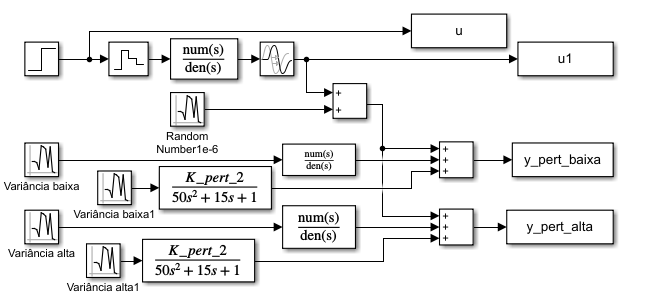

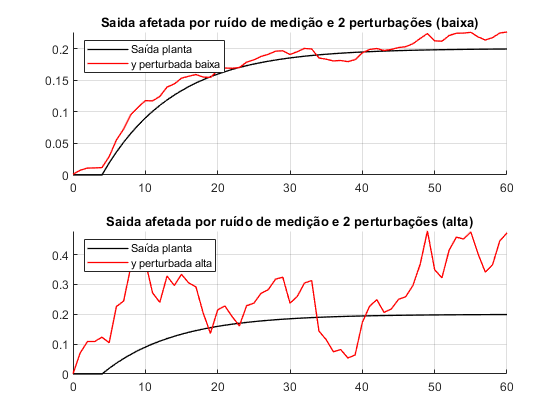


% Rodando simulação do Simulink
    Tsim = 60;
    sim('Lista_1_Simu_5');
% Sistema Contínuo
    Sisc1=tf(K_pert_1,[Tau_pert_1 1],'inputdelay',t_heta);
    Sisc2=tf(K_pert_2,[50 15 1],'inputdelay',t_heta);

% Convertendo para discreto
    Sisd1=c2d(Sisc1,1,'zoh');
    Sisd2=c2d(Sisc2,1,'zoh');

    
% Plotando o gráfico
ax1 = subplot(2,1,1);

    grf_bax = grf_bax + 1;
    figure(grf_bax);
    grid;
    hold on;
    plot(t,u1,'black','linewidth',lne);       % Degrau
    plot(t,y_pert_baixa,'red','linewidth',lne);     % Contínuo
    
    title({'Saida afetada por ruído de medição e 2 perturbações (baixa)'});
    legend('Saída planta','y perturbada baixa','location','northwest');
  
    
% Plotando o gráfico
ax2 = subplot(2,1,2);

    grf_alt = grf_alt + 1;
    figure(grf_alt);
    grid;
    hold on;
    plot(t,u1,'black','linewidth',lne);       % Degrau
    plot(t,y_pert_alta,'red','linewidth',lne);     % Contínuo
    
    
    title({'Saida afetada por ruído de medição e 2 perturbações (alta)'});
    legend('Saída planta','y perturbada alta','location','northwest');

**Comentários: **Observando que mesmo com as perturbações passando pelos filtros, a de alta variância compromete bastante a saída da planta.

**F**. Para os dois processos do item anterior, com perturbações alta e baixa, seria possível estimar, com base na resposta ao degrau (identificação não-paramétrica baseada na curva de  reação do processo), um modelo para o sistema e seus parâmetros? Em caso afirmativo,  qual seria esse modelo e seus parâmetros? Compare a saída do modelo aproximado com a  saída do processo sem perturbação quando excitados pelo mesmo degrau. Estime também o tempo de acomodação aproximado do processo ts ao se empregar perturbações de baixa  intensidade. 

    
clc;clear;close all;

% Variáveis...
    grf=0;
    lne=1;
    
    %variâncias
    bax=0.001;
    alt=0.1;
    variante=1e-6;
    
    k=2;
    tau=10;
    t_heta=4;
    
    K_pert_1=1;
    Tau_pert_1=5;
    
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;
    
    K2=2;
    TAU2=9.45;
    t_heta2=2.884;
       

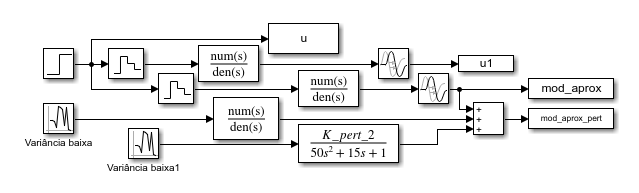

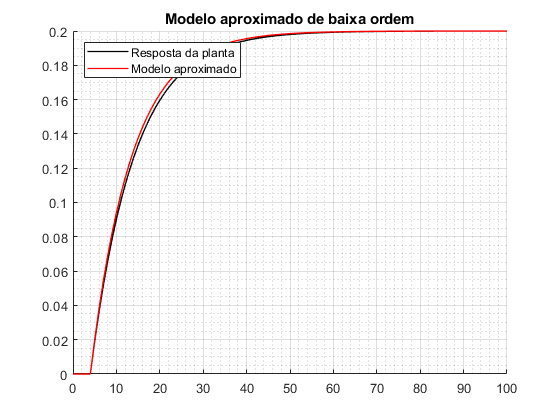

% Rodando simulação do Simulink
    Tsim = 100;
    sim('Lista_1_Simu_6');
    
% Plotando o gráfico

    grf = grf + 1;
    figure(grf);
    grid on;
    grid minor;
    hold on;
    plot(t,u1,'black','linewidth',lne);       % Degrau
    plot(t,mod_aprox,'red','linewidth',lne);     % Contínuo

    %
    title({'Modelo aproximado de baixa ordem'});
    legend('Resposta da planta','Modelo aproximado','location','northwest');

Aplicando uma preturbação ao modelo aproximado, temos:

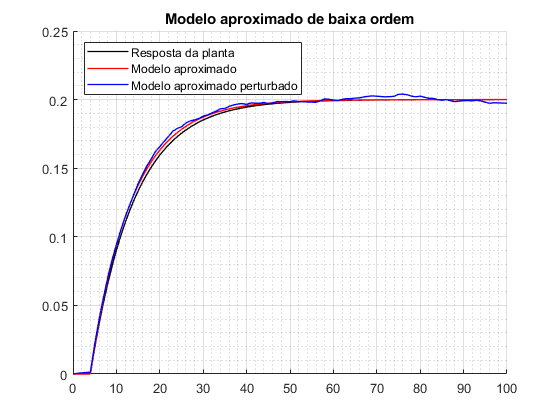

    % Rodando simulação do Simulink
    Tsim = 100;
    sim('Lista_1_Simu_6');
    
% Plotando o gráfico

    grf = grf + 1;
    figure(grf);
    grid on;
    grid minor;
    hold on;
    plot(t,u1,'black','linewidth',lne);       % Degrau
    plot(t,mod_aprox,'red','linewidth',lne);     % Contínuo
    plot(t,mod_aprox_pert,'blue','linewidth',lne);
    
    %
    title({'Modelo aproximado de baixa ordem'});
    legend('Resposta da planta','Modelo aproximado','Modelo aproximado perturbado','location','northwest');

**Comentários: **Observando que mesmo com as perturbações passando pelos filtros, a de alta variância compromete bastante a saída da planta.

**G**. Excite o processo com um pulso unitário e registre a saída do mesmo, considerando a  saída y limpa (sem perturbações nem ruído de medição) e a saída y2 afetada por ambas as  perturbações (v1 e v2) com baixa e alta intensidade e por ruído de medição. Simule a planta  por 2*ts. É possível nas três saídas medidas enxergar bem a função-peso do sistema? 

clc;clear;close all;

% Variáveis...
    grf_bax=0;
    grf_alt=0;
    
    lne=1;
    %variâncias
    bax=0.001;
    alt=0.1;
    variante=1e-6;
    
    k=2;
    tau=10;
    K_pert_1=1;
    Tau_pert_1=5;
    t_heta=4;
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;
    

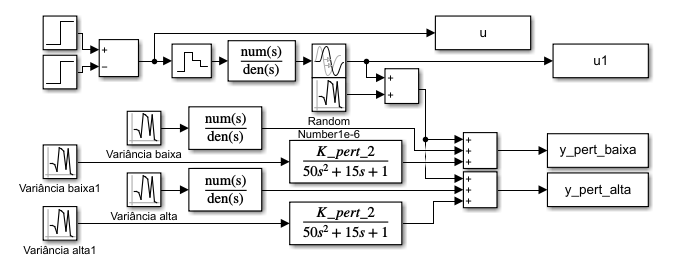

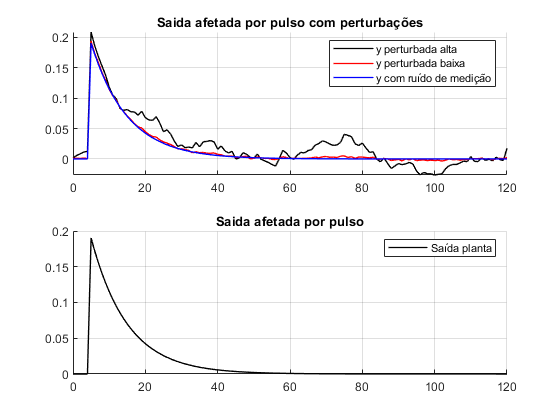

% Rodando simulação do Simulink
    Tsim = 120;
    sim('Lista_1_Simu_7');
% Sistema Contínuo
    Sisc1=tf(K_pert_1,[Tau_pert_1 1],'inputdelay',t_heta);
    Sisc2=tf(K_pert_2,[50 15 1],'inputdelay',t_heta);

% Convertendo para discreto
    Sisd1=c2d(Sisc1,1,'zoh');
    Sisd2=c2d(Sisc2,1,'zoh');

    
% Plotando o gráfico
ax1 = subplot(2,1,1);

    grf_bax = grf_bax + 1;
    figure(grf_bax);
    grid;
    hold on;
    plot(t,y_pert_alta,'black','linewidth',lne);       % Degrau
    plot(t,y_pert_baixa,'red','linewidth',lne);     % Contínuo
    plot(t,u1,'blue','linewidth',lne);     % Contínuo
    
    title({'Saida afetada por pulso com perturbações'});
    legend('y perturbada alta','y perturbada baixa','y com ruído de medição','location','northeast');  
    
% Plotando o gráfico
ax2 = subplot(2,1,2);

    grf_alt = grf_alt + 1;
    figure(grf_alt);
    grid;
    hold on;
    plot(t,u1,'black','linewidth',lne);       % Degrau
    %plot(t,y_pert_alta,'red','linewidth',lne);     % Contínuo
    
    
    title({'Saida afetada por pulso'});
    legend('Saída planta','location','northeast');

**Comentários: **Com a perturbação em alta amplitude, não podemos enxergar a função peso do sistema, mas com a perturbação de baixa, conseguimos visualizar, mas percebemos que está sendo perturbada.

**H**. Empregue as três respostas impulsivas obtidas no item anterior para determinar a resposta  a um degrau de amplitude 0,1 aplicado em t=0 s, via somatório de convolução. 

clc;clear;close all;

% Variáveis...
    grf=0;
        
    lne=1;
    %variâncias
    bax=0.001;
    alt=0.1;
    variante=1e-6;
    
    T=1;
    
    k=2;
    tau=10;
    K_pert_1=1;
    Tau_pert_1=5;
    t_heta=4;
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;

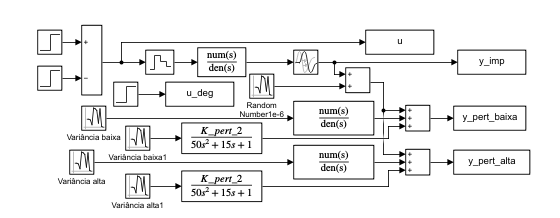

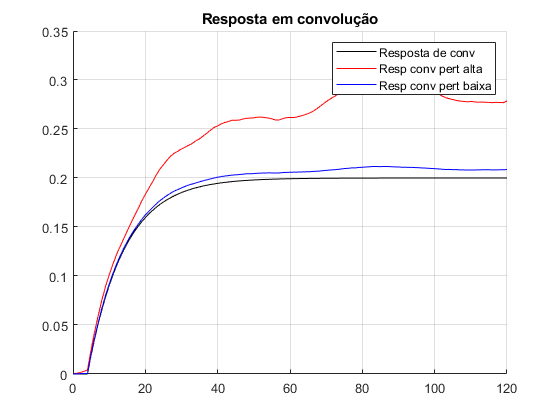

% Rodando simulação do Simulink
    Tsim = 120;
    sim('Lista_1_Simu_8');

    
% Convolução    
    
    %pega o comprimento da matriz das saídas
    L_imp=length(y_imp);            %saída ao impulso (limpa)
    L_imp_a=length(y_pert_alta);    %saída ao impulso com perturbaçção alta
    L_imp_b=length(y_pert_baixa);   %saída ao impulso com perturbaçção baixa
    L_deg=length(u_deg);            %sáida de um degrau de amplitude 0.1
    
    %calcula um valor de "te" para cada sáida
    te=1:L_imp+L_deg-1;             
    te_a=1:L_imp_a+L_deg-1;
    te_b=1:L_imp_b+L_deg-1;
    
    %salva as saídas em outras variaveis
    g=y_imp;
    g_a=y_pert_alta;
    g_b=y_pert_baixa;
    u=u_deg;
    
    %Cria a convolução de cada saída 
    yc=conv(g*T,u);
    yc_a=conv(g_a*T,u);
    yc_b=conv(g_b*T,u);
    
    
% Plotando o gráfico
    grf = grf + 1;
    figure(grf);
    grid;
    hold on;
    plot((te-1)*T,yc,'black')
    plot((te-1)*T,yc_a,'red')
    plot((te-1)*T,yc_b,'blue')
    xlim ([0 120]);
    title({'Resposta em convolução'});
    legend('Resposta de conv','Resp conv pert alta','Resp conv pert baixa','location','northeast');

**I.** Empregue o método da análise de correlação para estimar a função-peso do sistema. Para  tal, colete 1000 pontos do processo. Faça isso considerando a saída y limpa (sem  perturbações nem ruído de medição) e a saída y2 afetada por ambas as perturbações (v1 e  v2) com baixa e alta intensidade e por ruído de medição. Compare as funções-peso aqui  obtidas com aquela gerada no item anterior para a saída y limpa. 

clc;clear;close all;

%variâncias
    bax=0.001;
    
    T=1;
    
    k=2;
    tau=10;
    t_heta=4;

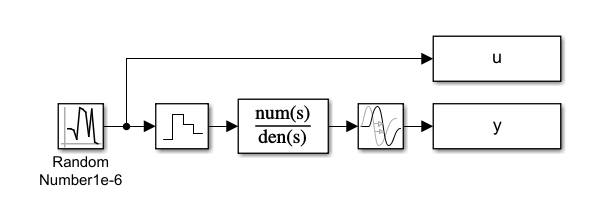

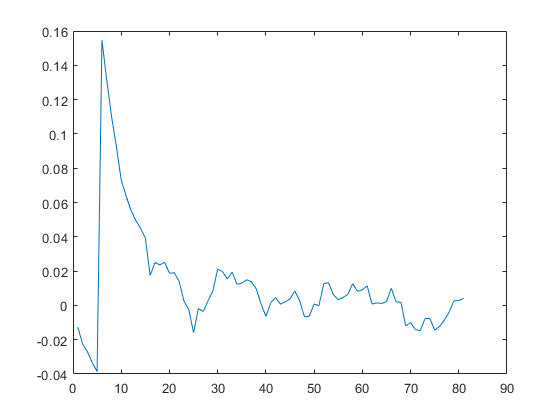

    Tsim = 1000;
    sim('Lista_1_Simu_9');    

vetor=[y u];    
ir=cra(vetor,80,0,0);
plot(ir);

j. Empregue as três respostas impulsivas obtidas no item anterior para determinar a resposta  a um degrau de amplitude 0,1 aplicado em t=0 s, via somatório de convolução. Compare as  respostas ao degrau obtidas aqui com aquelas obtidas no item “H”.

clc;clear;close all;

% Variáveis...
    grf=0;
        
    lne=1;
    %variâncias
    bax=0.001;
    alt=0.1;
    variante=1e-6;
    
    T=1;
    
    k=2;
    tau=10;
    K_pert_1=1;
    Tau_pert_1=5;
    t_heta=4;
    K_pert_2=2;
    Tau_pert_21=5;
    Tau_pert_22=10;
    

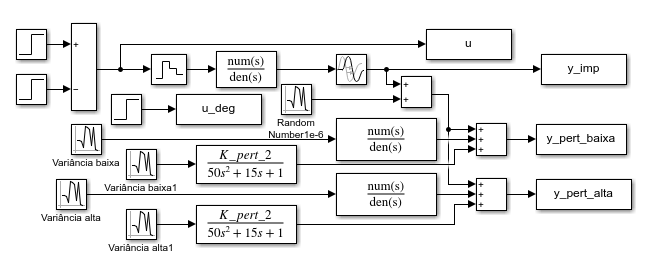

% Rodando simulação do Simulink
    Tsim = 120;
    sim('Lista_1_Simu_10');

% Convolução    
    
    %pega o comprimento da matriz das saídas
    L_imp=length(y_imp);            %saída ao impulso (limpa)
    L_imp_a=length(y_pert_alta);    %saída ao impulso com perturbaçção alta
    L_imp_b=length(y_pert_baixa);   %saída ao impulso com perturbaçção baixa
    L_deg=length(u_deg);            %sáida de um degrau de amplitude 0.1
    
    %calcula um valor de "te" para cada sáida
    te=1:L_imp+L_deg-1;             
    te_a=1:L_imp_a+L_deg-1;
    te_b=1:L_imp_b+L_deg-1;
    
    %salva as saídas em outras variaveis
    g=y_imp;
    g_a=y_pert_alta;
    g_b=y_pert_baixa;
    u=u_deg;
    
    %Cria a convolução de cada saída 
    yc=conv(g*T,u);
    yc_a=conv(g_a*T,u);
    yc_b=conv(g_b*T,u);
  
% Plotando o gráfico
    grf = grf + 1;
    figure(grf);
    grid;
    hold on;
    plot((te-1)*T,yc,'black')
    plot((te-1)*T,yc_a,'red')
    plot((te-1)*T,yc_b,'blue')
    xlim ([0 120]);
    title({'Resposta em convolução'});
    legend('Resposta de conv','Resp conv pert alta','Resp conv pert baixa','location','northeast');